# Homework 4 - Farshad Bolouri - R11630884

## Problem 1)

#### You are given the sound file noisy1.wav which contains a sinusoidal noise source on top of a voice recording. Your task is to design an IIR notch filter of order two that removes the noise source while keeping the voice source.

clear
close all

[noisy, fs] = audioread("noisy1.wav");

a) Determine the normalized frequency 𝜔0 of the sinusoidal noise signal and the physical frequency𝑓0. Explain how you proceeded.

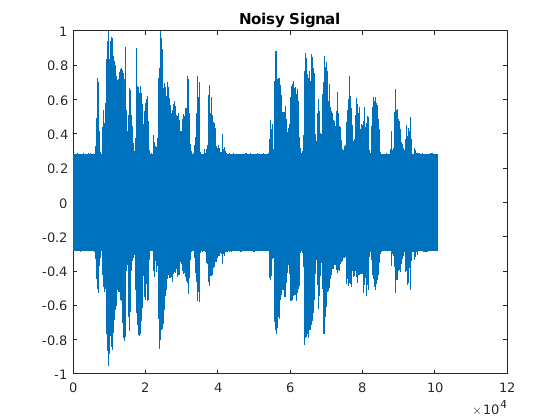

plot(noisy)
title('Noisy Signal')

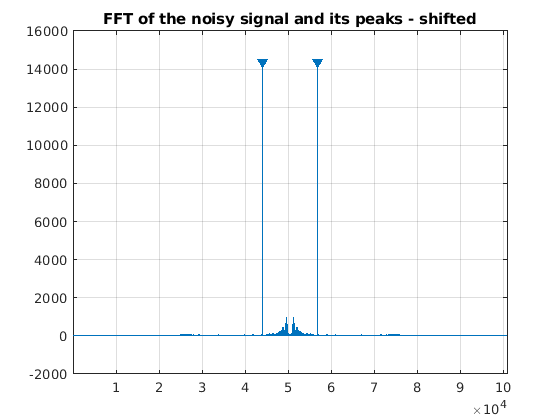

Y = fft(noisy);
findpeaks(abs(fftshift(Y)), 'MinPeakHeight',10000)
title('FFT of the noisy signal and its peaks - shifted')

*Finding *$\omega_0 \;$*and *$f_0$


$$\frac{f_0 }{f_s }=\frac{k}{N}$$


info = audioinfo("noisy1.wav")

info = struct with fields:
             Filename: '/var/Programs/DSP/noisy1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 16000
         TotalSamples: 100864
             Duration: 6.3040
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 16


[~, k] = max(abs(Y))

k = 6305

f0 = k / info.TotalSamples * fs

f0 = 1.0002e+03


$$f_0 \approx 1000\;\textrm{Hz}$$



$$\omega_0 =\frac{f_0 }{f_s }\cdot 2\pi \;$$


w0 = f0 / fs * 2 * pi

w0 = 0.3928


$$\omega_0 \approx 0\ldotp 3928\;\frac{\textrm{rad}}{s}$$


*SideNote: Another easy way to find *$f_0$* could be using the spectrogram of the noise signal:*

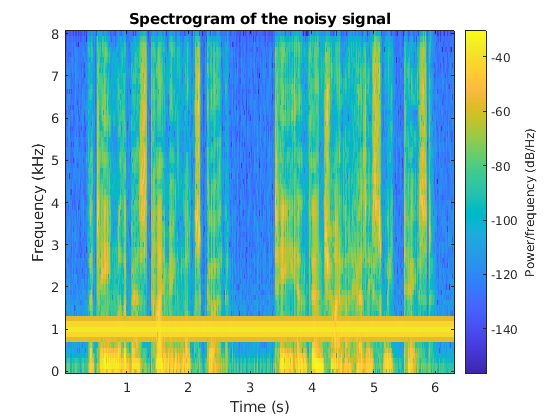

spectrogram(noisy,blackman(128),120,128,fs, 'yaxis')
title('Spectrogram of the noisy signal')

*You can clearly see our *$f_0$* being around 1000 Hz!*

b) Design the second order IIR notch filter. Graph its pole-zero plot and its frequency response

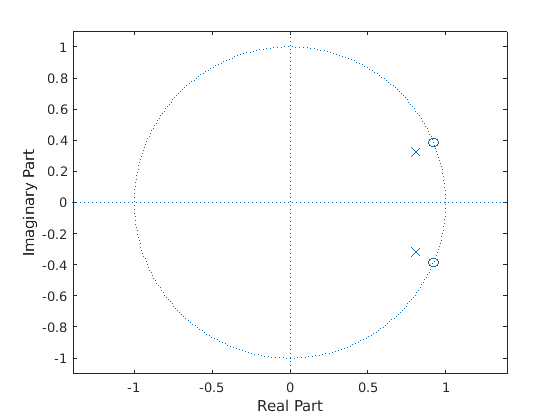

% Find filter coefficients using MATLAB's filter designer tool:
B = [ 0.854700854700854772971752026933245360851 -1.579280651439680438485879676591139286757...
     0.854700854700854772971752026933245360851];
A = [1.000 -1.611065108474535989557807624805718660355...
     0.75178718800825683477029315326944924891 ];

zplane(B, A)

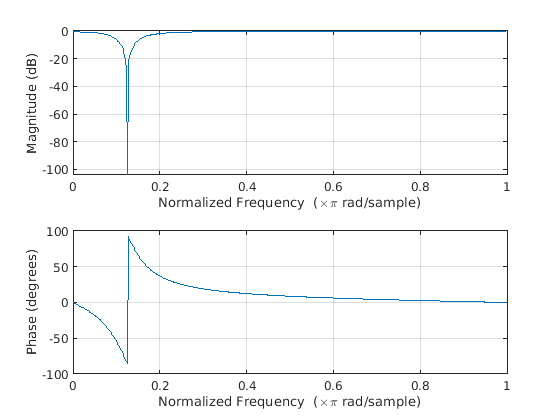

freqz(B, A)

c) Filter the signal in MATLAB and store the result as a wav-file. MATLAB functions that help you accomplish this task are audioread(), filter(), and audiowrite(). The MATLAB documentation provides you with information on how to use these functions.

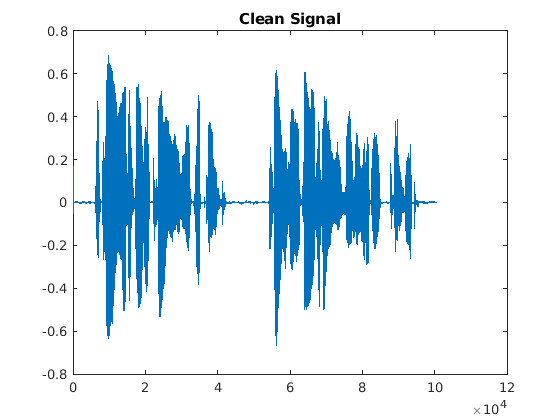

% Filtering the signal
clean = filter(B, A, noisy);

plot(clean)
title("Clean Signal")

audiowrite("clean.wav", clean, fs)

d) The closer you place your poles to the unit circle, the narrower the notch becomes. How do the filtered signals differ? Compare the performance of two notch filters to answer this question

*First we design our second and third filter:*

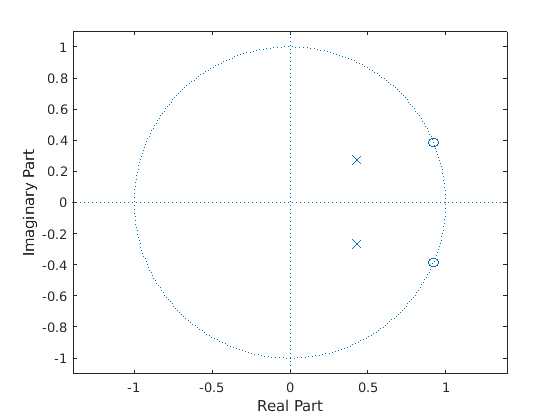

% Findig second filter coefficients using MATLAB's filter designer tool:
B2 = [  0.550000000000000044408920985006261616945 -1.01626709920143443177664721588371321559 ...
      0.550000000000000044408920985006261616945];
A2 = [1.000 -0.855432800959933459239437070209532976151...
      0.25632111506784238663669839297654107213];

figure
zplane(B2, A2)

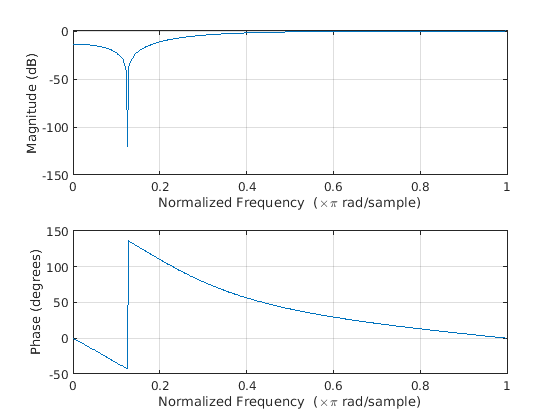

figure
freqz(B2,A2)
% Filtering the signal
secondFilt = filter(B2, A2, noisy);

subplot(2,1,1)

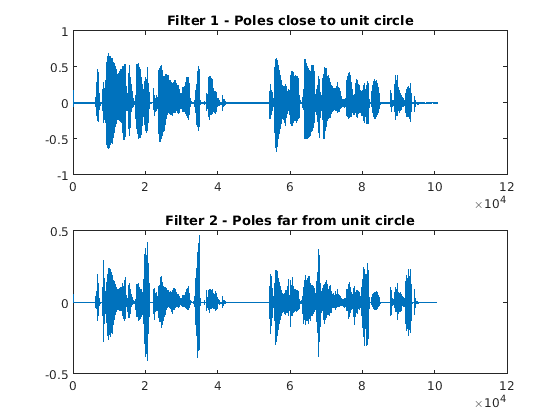

plot(clean)
title("Filter 1 - Poles close to unit circle")
subplot(2,1,2)
plot(secondFilt)
title("Filter 2 - Poles far from unit circle")

audiowrite("Poles_Far_From_UnitCircle.wav", secondFilt, fs)

*In the comparison of the two signals, you can see there's a bit of difference between two plots even whe you visually look at them.*

*After listening to the two signals, you can clearly tell that audio coming from the first filter (with the poles closer to the unit circle) is much clearer than the second filter.*

e) Your intention is to implement the notch filter on a digital signal processor (DSP), i.e. you need to implement the filtering operation yourself. You decide to try out this task in MATLAB first using a for loop that at each iteration uses the current input sample, the filter coefficients, and the values stored in the filter memory to calculate the current output sample. Implement your filter using Direct Form I. Save the resulting output vector as a wav-file.

% Implementing Direct Form I Structure
N = length(A);
Ax=A;
Bx=B;
signalReg = zeros(1,N);
outputReg = zeros(1,N);
output=0;
signal = zeros(1,length(noisy));

for i = 1:length(noisy)
    x=0;
    y=0;
    for j = N:-1:2
        outputReg(j) = outputReg(j-1); 
        signalReg(j) = signalReg(j-1);
        y=y- Ax(j)*outputReg(j);
        x=x+ Bx(j)*signalReg(j);
    end
    x=x+ Bx(1)*noisy(i);
    output=y+x;
    signalReg(1) = noisy(i);
    outputReg(1) = output;
    signal(i) = output;
end

audiowrite("Signal_Direct_Form_I.wav", signal, fs)

f) Compare the results obtained from part c) and part e), when using the same filter coefficients.

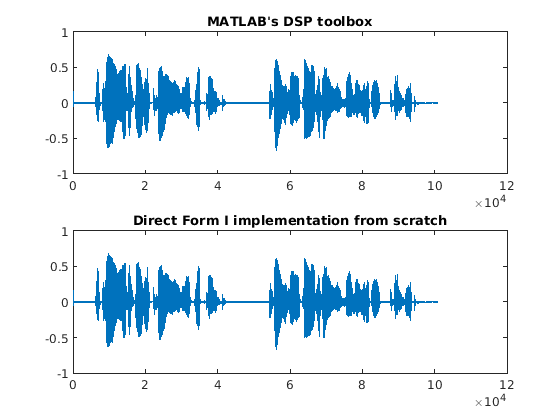

figure
subplot(2, 1, 1)
plot(clean)
title("MATLAB's DSP toolbox")
subplot(2,1,2)
plot(signal)
title("Direct Form I implementation from scratch")

*When looking at the two signals visually one can tell that the two signals are almost identitical. Also when listenning to the two audio files of each signal, telling the difference between the two is extremely difficult. Therefore it seems like our Direct Form I implementation has done a good job and it has been accurate.*

*Furthermore, let's look at the ****Mean-Squared Error ****between the two signals:*

immse(clean,signal')

ans = 8.4739e-33

*The error being basically zero means that our signals are identical. Once more confirming that our Direct Form I implementation has been accurate.*

## Problem 2)

Repeat tasks e) from Problem 1 using Direct Form II implementation. Then compare your new result to the results from part f) in Problem 1.

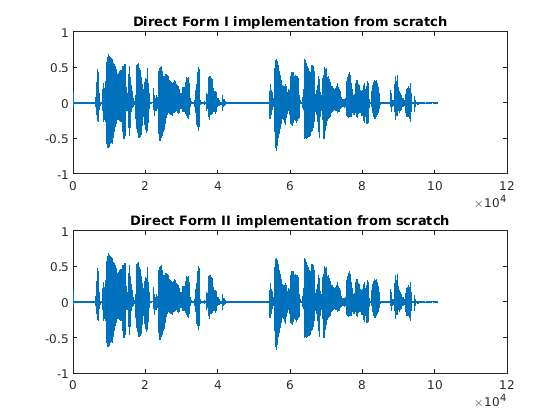

% Implementing Direct Form II structure
N = length(A);
Ax=A;
Bx=B;
signalReg = zeros(1,N);
output=0;
signal2 = zeros(1,length(noisy));

for i = 1:length(noisy)
    x=0;y=0;
    for j = N:-1:2
        signalReg(j) = signalReg(j-1);
        x=x- Ax(j)*signalReg(j);
        y=y+ Bx(j)*signalReg(j);
    end
    x = x + noisy(i);
    output=y+ Bx(1)*x;
    signalReg(1) = x;
    signal2(i) = output;
end

audiowrite("Signal_Direct_Form_II.wav", signal2, fs)

figure
subplot(2,1,1)
plot(signal)
title("Direct Form I implementation from scratch")
subplot(2,1,2)
plot(signal2)
title("Direct Form II implementation from scratch")

*Again, when looking at the two signals visually one can tell that the two signals are almost identitical. Also when listenning to the two audio files of each signal, telling the difference between the two is extremely difficult. Therefore it seems like our Direct Form II implementation has also done a good job and it has been accurate.*

*Furthermore, let's look at the ****Mean-Squared Error ****between the two signals:*

immse(signal,signal2)

ans = 1.1527e-31

*The error being basically zero means that our signals are identical. Once more confirming that our Direct Form II implementation has also been accurate.*